X = readtable('population_data.csv','Delimiter',';','VariableNamingRule',"preserve");
disp("The column names are: ")

The column names are: 


disp(X.Properties.VariableNames)  

  Columns 1 through 6

    {'Area'}    {'Total'}    {'0-4y'}    {'5-9y'}    {'10-14y'}    {'15-19y'}

  Columns 7 through 12

    {'20-24y'}    {'25-29y'}    {'30-34y'}    {'35-39y'}    {'40-44y'}    {'45-49y'}

  Columns 13 through 18

    {'50-54y'}    {'55-59y'}    {'60-64y'}    {'65-69y'}    {'70-74y'}    {'75-79y'}

  Columns 19 through 21

    {'80-84y'}    {'85-89y'}    {'90-y'}



dissimilarities1 = pdist(X{2:end,3:end}, "euclidean"); % compute pairwise Euclidean distances between the municipalities
[Y1,stress1,disparities1] = mdscale(dissimilarities1, 2,'criterion','metricstress','Options',statset('MaxIter', 1000, 'TolFun',1e-9));
distances1 = pdist(Y1);

% Define the labels for the cities
city_labels = X{2:end, 1};

% Find the indices for the three cities
helsinki_idx = find(strcmp(city_labels, 'Helsinki'));
espoo_idx = find(strcmp(city_labels, 'Espoo'));
vantaa_idx = find(strcmp(city_labels, 'Vantaa'));
tampere_idx = find(strcmp(city_labels, 'Tampere'));
turku_idx = find(strcmp(city_labels, 'Turku'));
rovaniemi_idx = find(strcmp(city_labels, 'Rovaniemi'));

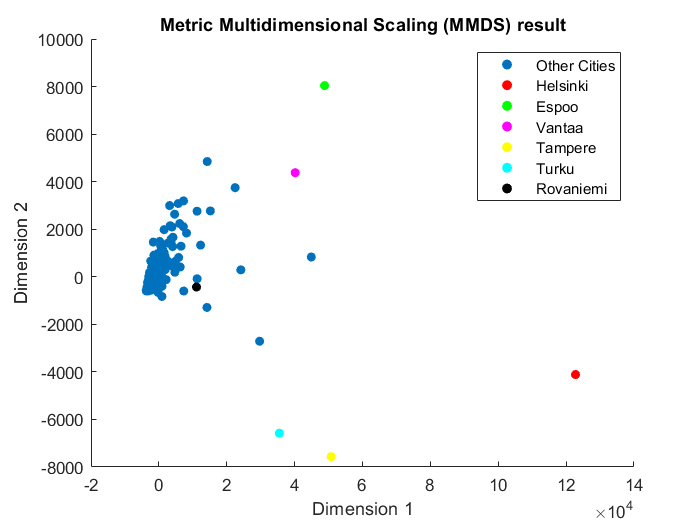

% Create a scatter plot with the three cities highlighted in red, green, and yellow, respectively
figure;
scatter(Y1(:, 1), Y1(:, 2), 30, 'filled');
hold on;
scatter(Y1(helsinki_idx, 1), Y1(helsinki_idx, 2), 30, 'r', 'filled');
scatter(Y1(espoo_idx, 1), Y1(espoo_idx, 2), 30, 'g', 'filled');
scatter(Y1(vantaa_idx, 1), Y1(vantaa_idx, 2), 30, 'm', 'filled');
scatter(Y1(tampere_idx, 1), Y1(tampere_idx, 2), 30, 'y', 'filled');
scatter(Y1(turku_idx, 1), Y1(turku_idx, 2), 30, 'cyan', 'filled');
scatter(Y1(rovaniemi_idx, 1), Y1(rovaniemi_idx, 2), 30, 'black', 'filled');
xlabel('Dimension 1');
ylabel('Dimension 2');
title('Metric Multidimensional Scaling (MMDS) result');
legend({'Other Cities', 'Helsinki', 'Espoo', 'Vantaa','Tampere','Turku','Rovaniemi'}, 'Location', 'northeast');

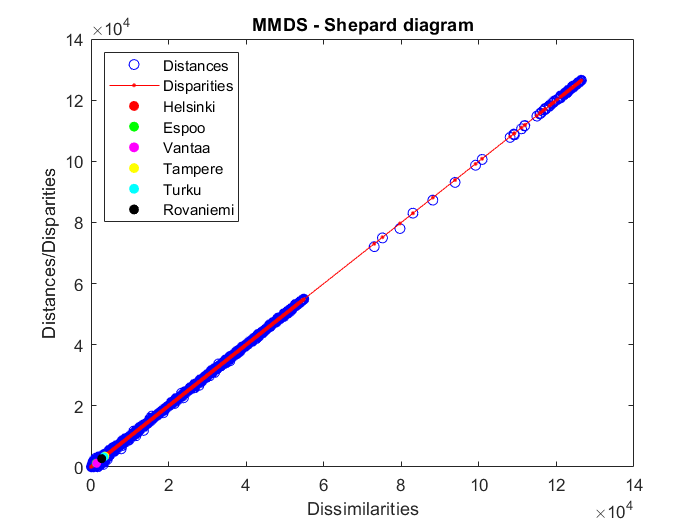

figure;
[dum1,ord1] = sortrows([disparities1(:) dissimilarities1(:)]);
plot(dissimilarities1,distances1,'bo', ...
dissimilarities1(ord1),disparities1(ord1),'r.-');
hold on;
scatter(dissimilarities1(helsinki_idx), distances1(helsinki_idx), 30, 'r', 'filled');
scatter(dissimilarities1(espoo_idx), distances1(espoo_idx), 30, 'g', 'filled');
scatter(dissimilarities1(vantaa_idx), distances1(vantaa_idx), 30, 'm', 'filled');
scatter(dissimilarities1(tampere_idx), distances1(tampere_idx), 30, 'y', 'filled');
scatter(dissimilarities1(turku_idx), distances1(turku_idx), 30, 'cyan', 'filled');
scatter(dissimilarities1(rovaniemi_idx), distances1(rovaniemi_idx), 30, 'black', 'filled');

title("MMDS - Shepard diagram")
xlabel('Dissimilarities'); ylabel('Distances/Disparities')
legend({'Distances','Disparities', 'Helsinki', 'Espoo', 'Vantaa','Tampere','Turku','Rovaniemi'}, 'Location', 'NW');

rho1 = corr(dissimilarities1', distances1', 'type', 'Spearman')

rho1 = 0.9969

disp(rho1)

    0.9969



average_relative_error1 = sum(abs(dissimilarities1 - distances1)) / sum(dissimilarities1);
disp(average_relative_error1)

    0.0080



dissimilarities2 = pdist(X{2:end,3:end}, "euclidean"); % compute pairwise Euclidean distances between the municipalities
[Y2,stress2,disparities2] = mdscale(dissimilarities2, 2,'criterion','sammon','Options',statset('MaxIter', 1000, 'TolFun',1e-9));
distances2 = pdist(Y2);

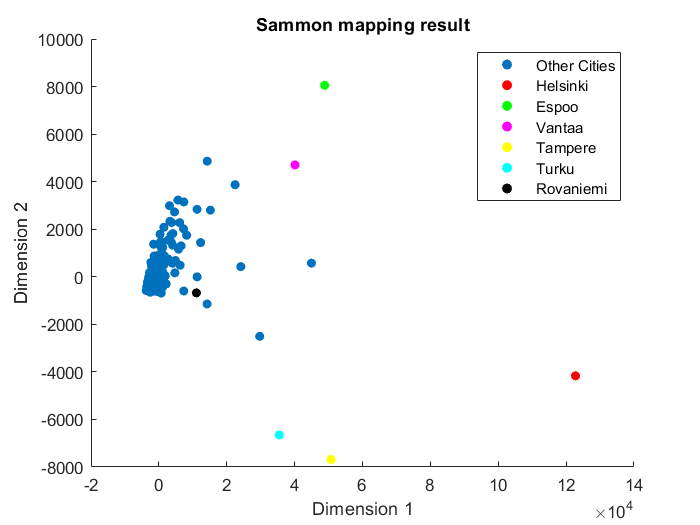

% Create a scatter plot with the three cities highlighted in red, green, and yellow, respectively
figure;
scatter(Y2(:, 1), Y2(:, 2), 30, 'filled');
hold on;
scatter(Y2(helsinki_idx, 1), Y2(helsinki_idx, 2), 30, 'r', 'filled');
scatter(Y2(espoo_idx, 1), Y2(espoo_idx, 2), 30, 'g', 'filled');
scatter(Y2(vantaa_idx, 1), Y2(vantaa_idx, 2), 30, 'm', 'filled');
scatter(Y2(tampere_idx, 1), Y2(tampere_idx, 2), 30, 'y', 'filled');
scatter(Y2(turku_idx, 1), Y2(turku_idx, 2), 30, 'cyan', 'filled');
scatter(Y2(rovaniemi_idx, 1), Y2(rovaniemi_idx, 2), 30, 'black', 'filled');
xlabel('Dimension 1');
ylabel('Dimension 2');
title('Sammon mapping result');
legend({'Other Cities', 'Helsinki', 'Espoo', 'Vantaa','Tampere','Turku','Rovaniemi'}, 'Location', 'northeast');

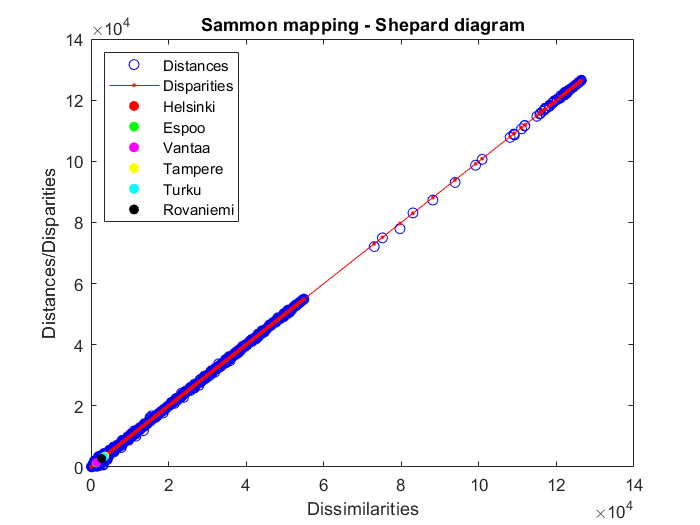

figure;
[dum2,ord2] = sortrows([disparities2(:) dissimilarities2(:)]);
plot(dissimilarities2,distances2,'bo', ...
dissimilarities2(ord2),disparities2(ord2),'r.-');
hold on;
scatter(dissimilarities2(helsinki_idx), distances2(helsinki_idx), 30, 'r', 'filled');
scatter(dissimilarities2(espoo_idx), distances2(espoo_idx), 30, 'g', 'filled');
scatter(dissimilarities2(vantaa_idx), distances2(vantaa_idx), 30, 'm', 'filled');
scatter(dissimilarities2(tampere_idx), distances2(tampere_idx), 30, 'y', 'filled');
scatter(dissimilarities2(turku_idx), distances2(turku_idx), 30, 'cyan', 'filled');
scatter(dissimilarities2(rovaniemi_idx), distances2(rovaniemi_idx), 30, 'black', 'filled');

title("Sammon mapping - Shepard diagram")
xlabel('Dissimilarities'); ylabel('Distances/Disparities')
legend({'Distances','Disparities', 'Helsinki', 'Espoo', 'Vantaa','Tampere','Turku','Rovaniemi'}, 'Location', 'NW');

rho2 = corr(dissimilarities2', distances2', 'type', 'Spearman')

rho2 = 0.9987

disp(rho2)

    0.9987



average_relative_error2 = sum(abs(dissimilarities2 - distances2)) / sum(dissimilarities2);
disp(average_relative_error2)

    0.0071

